# Example script how to use PIVlab from the commandline

Just run this script to see what it does.

You can also adjust the settings in "s" and "p", specify a mask and a region of interest

clc; clear variables; close all
pivlab_dir = fileparts(which("buildfile.m"));
addpath(pivlab_dir); %add the PIVlab folder to search path

Select a number > 1 if you want to use the parallel computing toolbox to perform parallel computing:

nr_of_cores = 1; % integer, 1 means single core, greater than 1 means parallel

## Image files location:

image_root_dir = fullfile(pivlab_dir,'..','data_from_william','stereo_2'); %directory containing the images you want to analyze
image_dir = fullfile(image_root_dir, "PIV images1");
image_ext = 'tif'; % bmp / tif / jpg / tiff / jpeg
pairwise = true; % false for [A+B], [B+C], [C+D]... sequencing style, and true for [A+B], [C+D], [E+F]... sequencing style

## Calibration image settings and files

pattern_type = "charuco-board";
pattern_dims = [7 10];
pattern_name = "DICT_5X5_100";
checker_size = 8.8;  % 100 pixels / 300 pixels-per-inch * 26.4 mm-per-inch)
marker_size = 0.75 * checker_size;

calibration_dir = fullfile(image_root_dir,"moving board");
n_calibration_files = 5;

## Standard PIV Settings

settings = cell(15,2); % To make it more readable, let's create a "settings table"
%Parameter                          %Setting			%Options
settings{1,1}= 'Int. area 1';              settings{1,2}=64;			% window size of first pass
settings{2,1}= 'Step size 1';              settings{2,2}=32;			% step of first pass
settings{3,1}= 'Subpix. finder';           settings{3,2}=1;			% 1 = 3point Gauss, 2 = 2D Gauss
settings{4,1}= 'Mask';                     settings{4,2}=[];			% If needed, supply a binary image mask with the same size as the PIV images
settings{5,1}= 'ROI';                      settings{5,2}=[];			% Region of interest: [x,y,width,height] in pixels, may be left empty to process the whole image
settings{6,1}= 'Nr. of passes';            settings{6,2}=2;			% 1-4 nr. of passes
settings{7,1}= 'Int. area 2';              settings{7,2}=32;			% second pass window size
settings{8,1}= 'Int. area 3';              settings{8,2}=16;			% third pass window size
settings{9,1}= 'Int. area 4';              settings{9,2}=16;			% fourth pass window size
settings{10,1}='Window deformation';       settings{10,2}='*linear';	% '*spline' is more accurate, but slower
settings{11,1}='Repeated Correlation';     settings{11,2}=0;			% 0 or 1 : Repeat the correlation four times and multiply the correlation matrices.
settings{12,1}='Disable Autocorrelation';  settings{12,2}=0;			% 0 or 1 : Disable Autocorrelation in the first pass.
settings{13,1}='Correlation style';        settings{13,2}=0;			% 0 or 1 : Use circular correlation (0) or linear correlation (1).
settings{14,1}='Repeat last pass';			settings{14,2}=0;			% 0 or 1 : Repeat the last pass of a multipass analyis
settings{15,1}='Last pass quality slope';  settings{15,2}=0.025;		% Repetitions of last pass will stop when the average difference to the previous pass is less than this number.

## Standard image preprocessing settings

preprocessing = cell(10,1);
%Parameter                       %Setting           %Options
preprocessing{1,1}= 'ROI';                   preprocessing{1,2}=settings{5,2};     % same as in PIV settings
preprocessing{2,1}= 'CLAHE';                 preprocessing{2,2}=1;          % 1 = enable CLAHE (contrast enhancement), 0 = disable
preprocessing{3,1}= 'CLAHE size';            preprocessing{3,2}=50;         % CLAHE window size
preprocessing{4,1}= 'Highpass';              preprocessing{4,2}=0;          % 1 = enable highpass, 0 = disable
preprocessing{5,1}= 'Highpass size';         preprocessing{5,2}=15;         % highpass size
preprocessing{6,1}= 'Clipping';              preprocessing{6,2}=0;          % 1 = enable clipping, 0 = disable
preprocessing{7,1}= 'Wiener';                preprocessing{7,2}=0;          % 1 = enable Wiener2 adaptive denoise filter, 0 = disable
preprocessing{8,1}= 'Wiener size';           preprocessing{8,2}=3;          % Wiener2 window size
preprocessing{9,1}= 'Minimum intensity';     preprocessing{9,2}=0.0;        % Minimum intensity of input image (0 = no change)
preprocessing{10,1}='Maximum intensity';     preprocessing{10,2}=1.0;       % Maximum intensity on input image (1 = no change)


## Postprocessing settings

postprocessing = cell(6,1);
%Parameter     %Setting                                     %Options
postprocessing{1,1}= 'Calibration factor, 1 for uncalibrated data';      postprocessing{1,2}=1;                   % Calibration factor for u
postprocessing{2,1}= 'Calibration factor, 1 for uncalibrated data';      postprocessing{2,2}=1;                   % Calibration factor for v
postprocessing{3,1}= 'Valid velocities [u_min; u_max; v_min; v_max]';    postprocessing{3,2}=[-50; 50; -50; 50];  % Maximum allowed velocities, for uncalibrated data: maximum displacement in pixels
postprocessing{4,1}= 'Stdev check?';                                     postprocessing{4,2}=1;                   % 1 = enable global standard deviation test
postprocessing{5,1}= 'Stdev threshold';                                  postprocessing{5,2}=7;                   % Threshold for the stdev test
postprocessing{6,1}= 'Local median check?';                              postprocessing{6,2}=1;                   % 1 = enable local median test
postprocessing{7,1}= 'Local median threshold';                           postprocessing{7,2}=3;                   % Threshold for the local median test


## Calibrate cameras

cam1_files = dir(fullfile(calibration_dir, ['CAM1*A.', image_ext]));
cam2_files = dir(fullfile(calibration_dir, ['CAM2*A.', image_ext]));
image_indices = [5,7,14,15,19,25,30,40,51,64];
cam1_files = cam1_files(image_indices);
cam2_files = cam2_files(image_indices);
cam1_files = strcat({cam1_files.folder}', filesep, {cam1_files.name}');
cam2_files = strcat({cam2_files.folder}', filesep, {cam2_files.name}');
image_size = size(imread(cam1_files{1}));

worldPoints = patternWorldPoints(pattern_type, pattern_dims, checker_size);
stereo_image_points = detectCharucoBoardPoints(cam1_files, cam2_files, pattern_dims, pattern_name, checker_size, marker_size);
stereo_parameters = estimateCameraParameters(stereo_image_points, worldPoints, ImageSize=image_size);

## Get transforms to laser light plane

CAM1_PIVlab_0000_A.tif
CAM1_PIVlab_0003_A.tif
CAM1_PIVlab_0006_A.tif
CAM1_PIVlab_0009_A.tif
CAM1_PIVlab_0012_A.tif
CAM1_PIVlab_0015_A.tif
CAM1_PIVlab_0018_A.tif
CAM1_PIVlab_0021_A.tif
CAM1_PIVlab_0024_A.tif
CAM1_PIVlab_0027_A.tif
CAM1_PIVlab_0030_A.tif
CAM1_PIVlab_0033_A.tif
CAM1_PIVlab_0036_A.tif
CAM1_PIVlab_0039_A.tif
CAM1_PIVlab_0042_A.tif
CAM1_PIVlab_0045_A.tif
CAM1_PIVlab_0048_A.tif


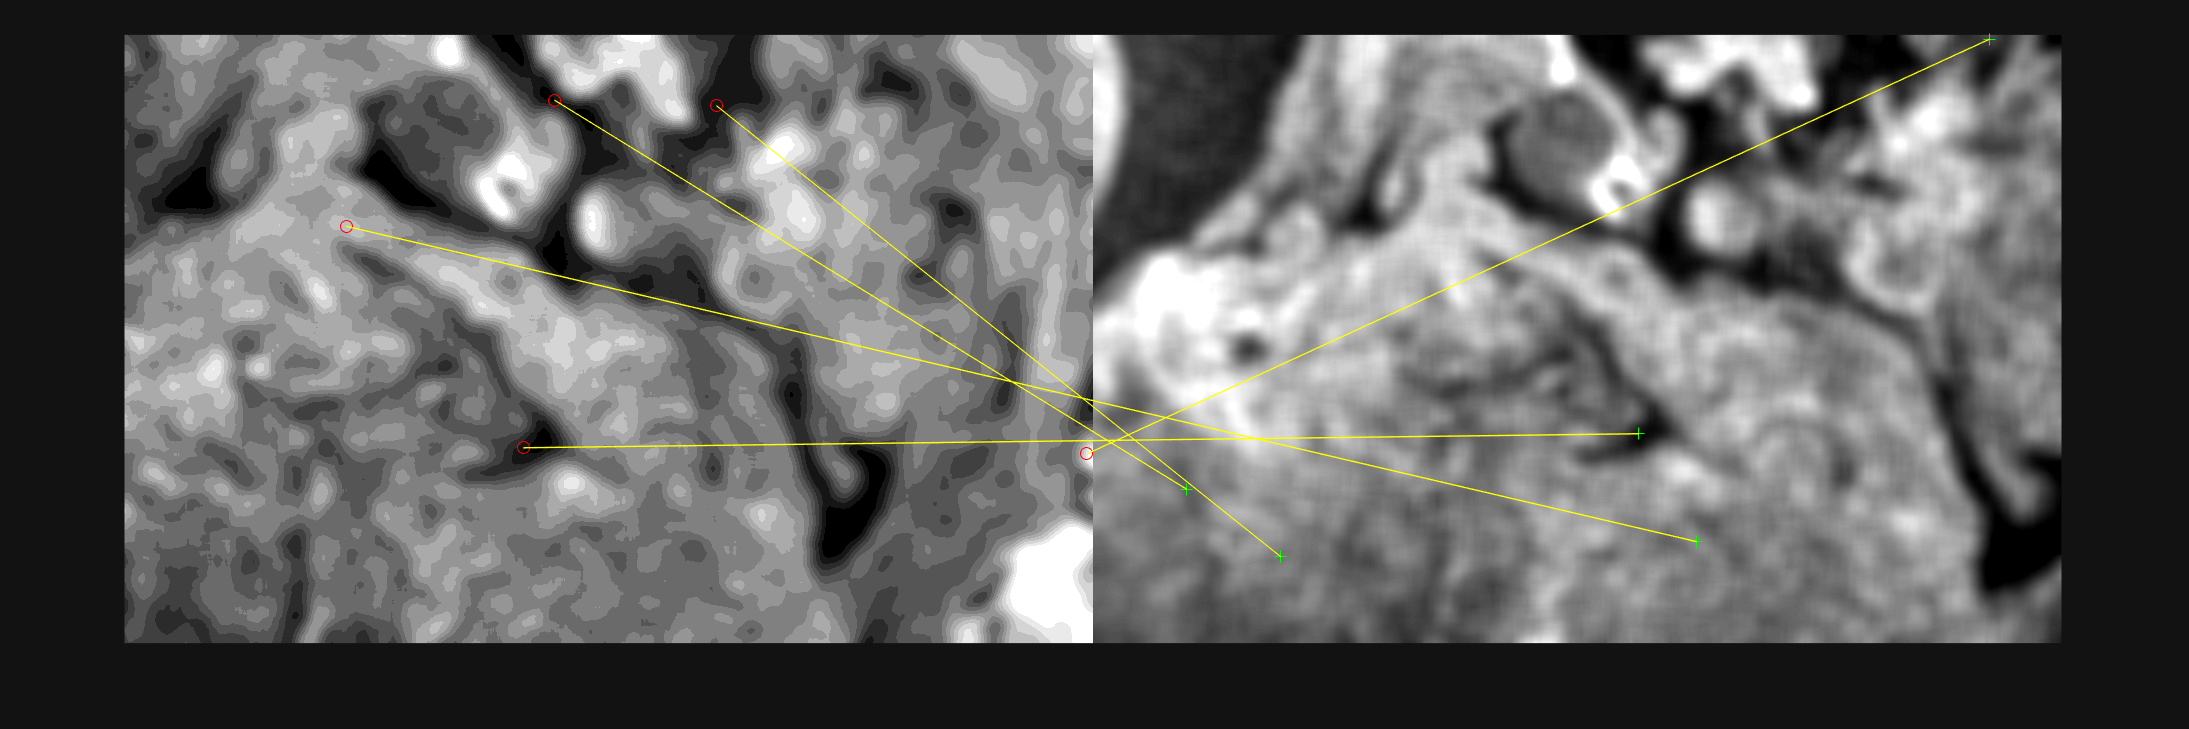

cam1_files = dir(fullfile(image_dir, filesep, ['CAM1*.', image_ext]));
cam2_files = dir(fullfile(image_dir, filesep, ['CAM2*.', image_ext]));
matchedPoints1 = {};
matchedPoints2 = {};
for indx = 1:6:length(cam1_files)
    img = imread(image_dir + filesep + cam1_files(indx).name);
    [img1, f1, points_obj1] = image_feature_extraction(img);

    img = imread(image_dir + filesep + cam2_files(indx).name);
    [img2, f2, points_obj2] = image_feature_extraction(img);
    
    indexPairs = matchFeatures(f1, f2, MatchThreshold=2, Unique=true); % MaxRatio=0.5);
    if size(indexPairs,1) > 0
        disp(cam1_files(indx).name)
        i1 = img1; i2 = img2;
        showMatchedFeatures(i1, i2, points_obj1(indexPairs(:,1)), points_obj2(indexPairs(:,2)), 'montage');
    end
    matchedPoints1{end+1} = points_obj1(indexPairs(:,1));
    matchedPoints2{end+1} = points_obj2(indexPairs(:,2));
end


mp1 = vertcat(matchedPoints1{:});
mp2 = vertcat(matchedPoints2{:});
[~,is_inlier,~] = estimateFundamentalMatrix( ...
    mp1.Location, ...
    mp2.Location, ...
    method="MSAC", ...
    Confidence=65, ...
    DistanceThreshold=10 ...
);

mp1 = mp1(is_inlier);
mp2 = mp2(is_inlier);
disp(find(is_inlier))

    19
    22
    23
    30
    31
    42
    43
    44
    47
    52
    57
    63
    64
    65
    69
    70
    74
    76
    77
    81
    88
    91
    92
    94
    96
    97
    98
   101
   106
   108
   112
   114
   118
   120
   121
   122
   132
   136
   144
   145
   149



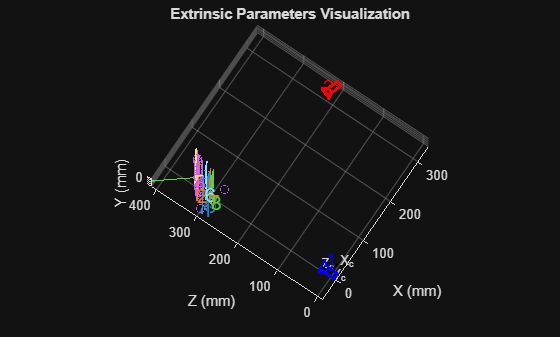


points = triangulate(mp1.Location, mp2.Location, stereo_parameters);
[coords, normal, mu] = two_d_coords_of_points(points);

figure
hold on
showExtrinsics(stereo_parameters)
scatter3(points(:,1), points(:,3), points(:,2))
quiver3(mu(1), mu(3), mu(2), normal(1), normal(3), normal(2), 100)
hold off

view([-47.5 85.5])

tform1 = fitgeotform2d(mp1.Location, coords, "projective");
tform2 = fitgeotform2d(mp2.Location, coords, "projective");

## Create list of images inside user specified directory

files = dir(fullfile(image_dir, ['*.', image_ext]));
filenames = string({files.name})';
filenames = sortrows(filenames); %sort all image files

## Pre-load the image names out side of the parallelizable loop

n_cameras = 2;
filenames = reshape(filenames, [], n_cameras);
cam1_filenames = reshape(filenames(:,1)', 2, [])';
cam2_filenames = reshape(filenames(:,2)', 2, [])';
slicedfilename1A = cellstr(cam1_filenames(:,1));
slicedfilename1B = cellstr(cam1_filenames(:,2));
slicedfilename2A = cellstr(cam2_filenames(:,1));
slicedfilename2B = cellstr(cam2_filenames(:,2));

ii = 1

ii = 1

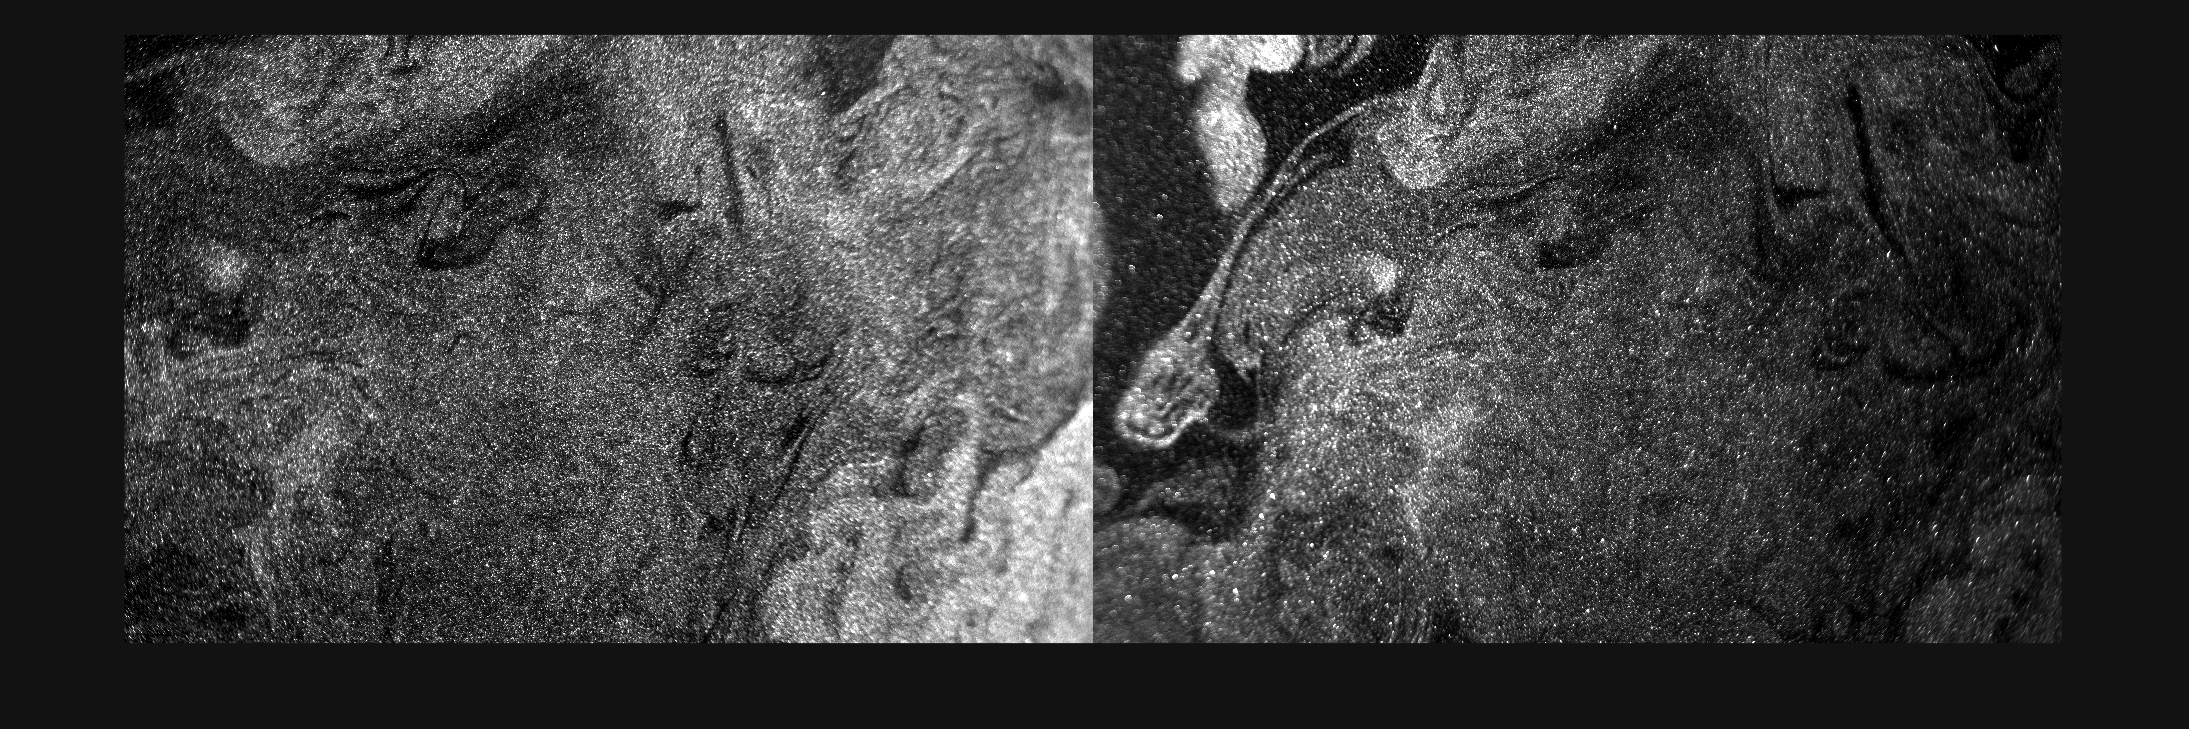


img1 = imread(fullfile(image_dir, slicedfilename1A{ii}));
img2 = imread(fullfile(image_dir, slicedfilename2A{ii}));
imshowpair(imadjust(img1), imadjust(img2),"montage")


[~, ref] = imwarp(img1, tform1, 'cubic'); % There may be a prettier way to get the ref object
ref.ImageSize = size(img1); % imwarp normally dramatically scales down the image
[img1, ~] = imwarp(img1, tform1, 'cubic', 'OutputView', ref);

[~, ref] = imwarp(img2, tform2, 'cubic'); % There may be a prettier way to get the ref object
ref.ImageSize = size(img2); % imwarp normally dramatically scales down the image
[img2, ~] = imwarp(img2, tform2, 'cubic', 'OutputView', ref);
imshowpair(imadjust(img1), imadjust(img2),"montage")

% [optimizer,metric] = imregconfig("monomodal");
% tform_base = imregtform( ...
%     imadjust(img2), ...
%     imadjust(img1), ...
%     "similarity", optimizer, metric ...
% );
% 
[img1t, f1, points_obj1] = image_feature_extraction(img1);
[img2t, f2, points_obj2] = image_feature_extraction(img2);
% 
% tform_base_2 = imregtform( ...
%     imadjust(img2t), ...
%     imadjust(img1t), ...
%     "similarity", optimizer, metric ...
% );


indexPairs = matchFeatures(f1, f2, MatchThreshold=10, Unique=true, MaxRatio=0.7);
[~,is_inlier,~] = estimateFundamentalMatrix( ...
    points_obj1(indexPairs(:,1)).Location, ...
    points_obj2(indexPairs(:,2)).Location, ...
    method="MSAC", ...
    Confidence=25, ...
    DistanceThreshold=50 ...
);
if size(indexPairs,1) > 0
    showMatchedFeatures(img1t, img2t, points_obj1(indexPairs(is_inlier,1)), points_obj2(indexPairs(is_inlier,2)), 'montage');
end
l1 = points_obj1(indexPairs(is_inlier,1)).Location;
l2 = points_obj2(indexPairs(is_inlier,2)).Location;
tform_base_new = fitgeotform2d(l2, l1, "similarity");
[img2a, ~] = imwarp(img2, tform_base, 'cubic', 'OutputView', imref2d(size(img1)));
[img2b, ~] = imwarp(img2, tform_base_new, 'cubic', 'OutputView', imref2d(size(img1)));
figure
imshowpair(imadjust(img1), imadjust(img2a))
figure
imshowpair(imadjust(img2), imadjust(img2b))

## Main PIV analysis

[x1, y1, u1, v1, typevector1, correlation_map1] = run_correlation(...
    image_dir, slicedfilename1A(1:5), slicedfilename1B(1:5), preprocessing, settings, nr_of_cores, tform1...
);
[x2, y2, u2, v2, typevector2, correlation_map2] = run_correlation(...
    image_dir, slicedfilename2A(1:5), slicedfilename2B(1:5), preprocessing, settings, nr_of_cores, tform2, tform_base ...
);

The most important results are x,y,u,v. These can now be viewed before validation:

ii = 4;
figure;
quiver(x1{ii},y1{ii},u1{ii},v1{ii},5);
axis image;  %(the last number determines the displayed sclae of the vectors)
title('Raw results of first image pair')



Calculate the angles to the vector positions relative to the camera axis. For the original image this should be trivial. It may be possible to use the tforms to figure move to the new coordinate systems.

cam1_intrinsic_params = stereo_parameters.CameraParameters1.Intrinsics;
[alpha1, beta1] = get_tan_angles(x1{1}, y1{1}, stereo_parameters.CameraParameters1.Intrinsics, tform1);
[alpha2, beta2] = get_tan_angles(x2{1}, y2{1}, stereo_parameters.CameraParameters2.Intrinsics, tform2);

Now calculate the new 3-d velocities using 

u = (u1 * tan(alpha2) + u2 * tan(alpha1)) / (tan(alpha1) + tan(alpha2))

v = (v1 * tan(beta2) + v2 * tan(beta2)) / (tan(beta1) + tan(beta2))

w = (u1 - u2) / (tan(alpha1) + tan(alpha2))

or

w = (v1 + v2) / (tan(beta1) + tan(beta2))

if one of the denominators approaches zero (eg $\tan \left(\beta 1\right)+\tan \left(\beta 2\right)$)  then use

v = 0.5 * (v1+v2) + 0.5 * w * (tan(beta1) - tan(beta2))

to avoid the singularity

U = cell(size(u1));
V = U;
W = U;
for indx = 1:length(u1)
    [U{indx}, V{indx}, W{indx}] = recover_3d_velocities( ...
        u1{indx}, v1{indx}, alpha1, beta1, u2{indx}, v2{indx}, alpha2, beta2 ...
    );
end



ii = 4;
figure;
hold on
wx = x2{ii};
wy = y2{ii};
wc = W{ii};
scatter(wx(:), wy(:), [], wc(:), "filled")
quiver(x2{ii}, y2{ii}, U{ii}, V{ii}, 5);
hold off
axis image;  %(the last number determines the displayed sclae of the vectors)
title('Raw results of first image pair')

## From here on is standard postprocessing for single camera PIV

disp("A break")

## PIV postprocessing loop

Standard image post processing settings

u_filt=cell(size(u));
v_filt=cell(size(v));
typevector_filt=typevector;

if nr_of_cores >1 % parallel loop

	if misc.pivparpool('size')<nr_of_cores
		misc.pivparpool('open',nr_of_cores);
	end

	parfor PIVresult=1:size(x,1)

		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},postprocessing,true);

	end

else % sequential loop

	for PIVresult=1:size(x,1)

		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},postprocessing,true);

	end

end

Post-processing finished, here are the filtered results:

figure;quiver(x{1},y{1},u_filt{1},v_filt{1},5);axis image; %(the last number determines the displayed sclae of the vectors)
title('Filtered results of first image pair')

## clean up parallel pool, and cluster (if required, will save RAM)

%{
if nr_of_cores >1 % parallel
	poolobj = gcp('nocreate'); % GET the current parallel pool
	if ~isempty(poolobj ); delete(poolobj );end
	clear local_cluster;
end
%}

Save the data to a Matlab file

save(fullfile(directory, [filenames{1} '_' filenames{end} '_' num2str(amount) '_frames_result_.mat']));

Clean up unused vars

clearvars -except p s r x y u v typevector directory filenames u_filt v_filt typevector_filt correlation_map
disp('DONE.')


Wrapper function for PIVlab_postproc

function [u_filt, v_filt,typevector_filt] = post_proc_wrapper(u,v,typevector,post_proc_setting,paint_nan)
% wrapper function for postproc.PIVlab_postproc

% INPUT
% u, v: u and v components of vector fields
% typevector: type vector
% post_proc_setting: post processing setting
% paint_nan: bool, whether to interpolate missing data

% OUTPUT
% u_filt, v_filt: post-processed u and v components of vector fields
% typevector_filt: post-processed type vector


[u_filt,v_filt] = postproc.PIVlab_postproc(u,v, ...
	post_proc_setting{1,2},...
	post_proc_setting{2,2},...
	post_proc_setting{3,2},...
	post_proc_setting{4,2},...
	post_proc_setting{5,2},...
	post_proc_setting{6,2},...
	post_proc_setting{7,2});

typevector_filt = typevector; % initiate
typevector_filt(isnan(u_filt))=2;
typevector_filt(isnan(v_filt))=2;
typevector_filt(typevector==0)=0; %restores typevector for mask

if paint_nan
	u_filt=misc.inpaint_nans(u_filt,4);
	v_filt=misc.inpaint_nans(v_filt,4);
end


end